# Operational modal analysis with a single accelerometer (example of a bridge)

## Summary

Some of the eigenfrequencies and modal damping ratios of a suspension bridge are identified using a single sensor, for example, a 3D accelerometer located near the shear centre of the girder. Because a single sensor is used, it is not possible to identify the mode shapes. All the data used herein are simulated. The sensor is not located at midspan so that it is possible to identify eigenfrequencies associated with both symmetric and antisymmetric mode shapes.

The method applied is described as follows:

- The first estimate of the eigenfrequencies is obtained by the classical peak-picking method. 

- A band-pass filter is applied to extract the modal response associated with the selected eigenfrequencies.

- The impulse-response function (IRF) is obtained by computing the autocorrelation function of each modal response.

- An exponential decay function is fitted to the IRF to estimate the damping ratios and obtain an improved estimate of the eigenfrequencies, as the peak-picking method is not always appropriate.

The present approach should not be applied to structure with closely-spaced modes, as the band-pas filter may not be able to split efficiently the two modal responses.

## Initialisation

Load simulated displacement data:

- *rz*: is the simulated vertical displacement response of the bridge in only one positions along the span. It is a [1 x N] matrix

- *zetaStruct*: target modal damping ratios for the different modes of the structure. It is a [M x 1] vector.

- *wn*: target vertical eigenmodes of the structure. It is a [M x 1] vector.

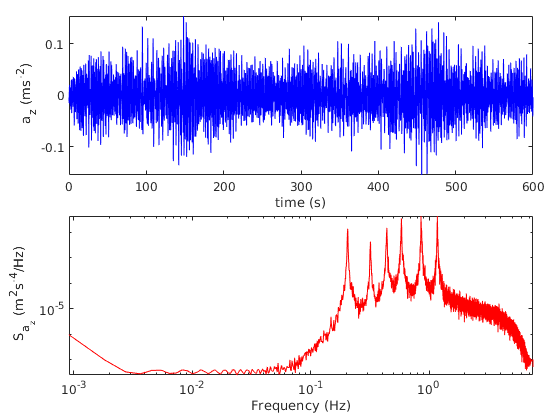

clearvars;close all;clc;
load('BridgeAccData.mat')


fnTarget = wn/(2*pi); % transform circular frequency (rad/s) into frequency (Hz)
dt = median(diff(t)); % get time step
fs=1/dt; % get sampling freuqency


% WARNING: You need Matlab R2019b or more recent version to use
% tiledlayout. Alternatively, you can use the older "subplot" functions.

clf;close all;
tiledlayout(2,1,"Padding","compact","TileSpacing","compact")
nexttile
plot(t,az,'b')
axis tight
xlim([0,600]);
xlabel('time (s)')
ylabel(' a_z (ms^{-2})')
nexttile
[Saz,f] = pwelch(detrend(az),[],[],[],fs);
loglog(f,Saz,'r');
axis tight
set(gca,'xscale','log')
xlabel('Frequency (Hz)')
ylabel(' S_{a_z} (m^2s^{-4}/Hz)')

set(gcf,'color','w')

## Method 1: Automated peak-picking method

If "plotOpt" is set to 1, intermediate figures are plotted to check the adequacy of the filtering and fitting.

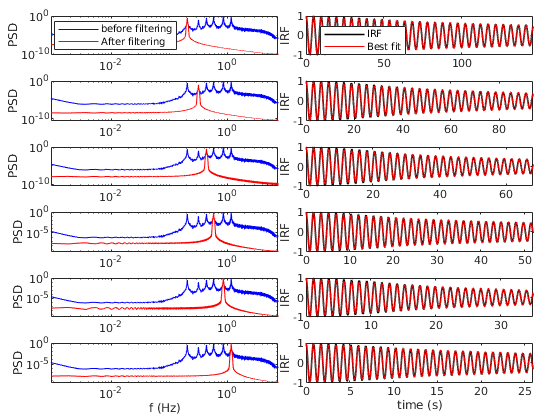

Nmodes = 6; % let says we want to identify 6 modes
Nperiod = 30; % The IRF is computed for 30 period on each mode
[fn,zeta] = modalID_singleSensor(az,Saz,f,Nmodes,fs,'plotOpt',1,'Nperiod',Nperiod);

### Comparison of the identified and target modal damping ratios

It is in general challenging to identify the modal damping ratios from ambient vibrations data. Therefore the agreement between the estimated and target modal damping ratios is here quite good.

T1 = table(zetaStruct(1:Nmodes),(round(zeta.*1e4)/1e4)','VariableNames',{'Target','Estimate'});
disp(T1)

    Target    Estimate
    ______    ________

    0.005      0.0034 
    0.005      0.0048 
    0.005      0.0052 
    0.005      0.0041 
    0.005       0.005 
    0.005      0.0036 



### Comparison of the identified and target eigenfrequencies

The small discrepancies at higher frequencies between the identified and target eigenfrequencies come from the numerical scheme used for the time-domain simulation of the bridge response, which relies on the Newmark-beta method. 

T2 = table((round(fnTarget(1:Nmodes)'.*1e3)/1e3),(round(fn(:).*1e3)/1e3),'VariableNames',{'Target','Estimate'});
disp(T2)

    Target    Estimate
    ______    ________

    0.205      0.205  
    0.319      0.319  
    0.439      0.438  
    0.585      0.583  
    0.864      0.855  
    1.194      1.171  



## Method 2: Manual peak-picking method

If "plotOpt" is set to 1, intermediate figures are plotted to check the adequacy of the filtering and fitting.

Peak selection procedure
a: Draw rectangles around peaks while holding left click
b: Press "Space" key to continue the peak selection
c: Press "any other key" if you have selected a peak by mistake and want to ignore it


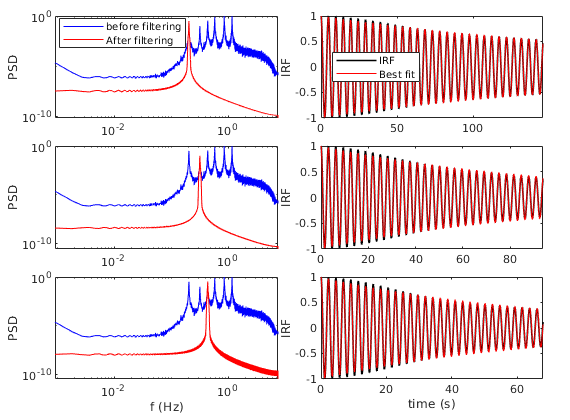

Nmodes = 3; % let says we want to identify 3 modes
Nperiod = 30; % The IRF is computed for 40 period on each mode
[fn,zeta] = modalID_singleSensor(az,Saz,f,Nmodes,fs,'plotOpt',1,'PickingMethod','manual');

### Comparison of the identified and target modal damping ratios

T1 = table(zetaStruct(1:Nmodes),(round(zeta.*1e4)/1e4)','VariableNames',{'Target','Estimate'});
disp(T1)

    Target    Estimate
    ______    ________

    0.005      0.0034 
    0.005      0.0048 
    0.005      0.0052 



### Comparison of the identified and target eigenfrequencies

T2 = table((round(fnTarget(1:Nmodes)'.*1e3)/1e3),(round(fn(:).*1e3)/1e3),'VariableNames',{'Target','Estimate'});
disp(T2)

    Target    Estimate
    ______    ________

    0.205      0.205  
    0.319      0.319  
    0.439      0.438  

